number ="5345345";
 
number = split(number,"");
keys = number(2:end-1);
Fs = 16384;
L = 0.3;
sinyal = [];

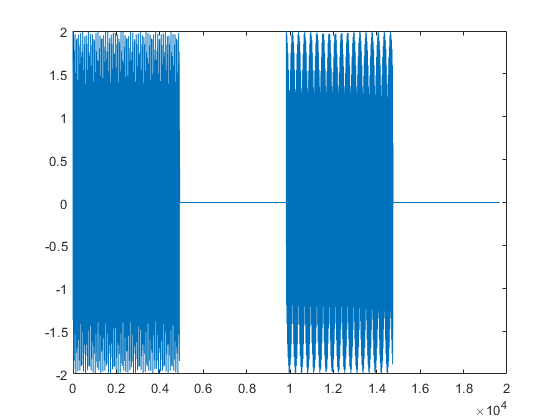

%Loop over the key length
for k= 1:length(keys)
    [frqs, t, t10ms, s, s10ms] = dtmf(keys(k)); % call dtmf 
    sinyal = [sinyal,s]; % add a 0.3 sec  signal 
    sinyal = [sinyal,zeros(size(t))]; % add a 0.3 sec  silence 
end
plot(sinyal);

save('sinyal.mat',"Fs","sinyal","L");  % saving all variabls
save('sinyal.wav',"sinyal")

sound(sinyal);